mMoon =7.348e22;% kg
mEarth = 5.9742e24; %kg
mu = mMoon/(mMoon + mEarth);
conditions1 = 1 - mu

conditions1 = 0.9878

k = 100

k = 100

periodo = 3.7837

periodo = 3.7837

X0 = [0.786717447531649 0 0 0.424560784056642]

X0 =     0.7867         0         0    0.4246


C1 = jacobiConstant([0.786717447531649 0],[0 0.424560784056642],mu)

C1 = 3.0326

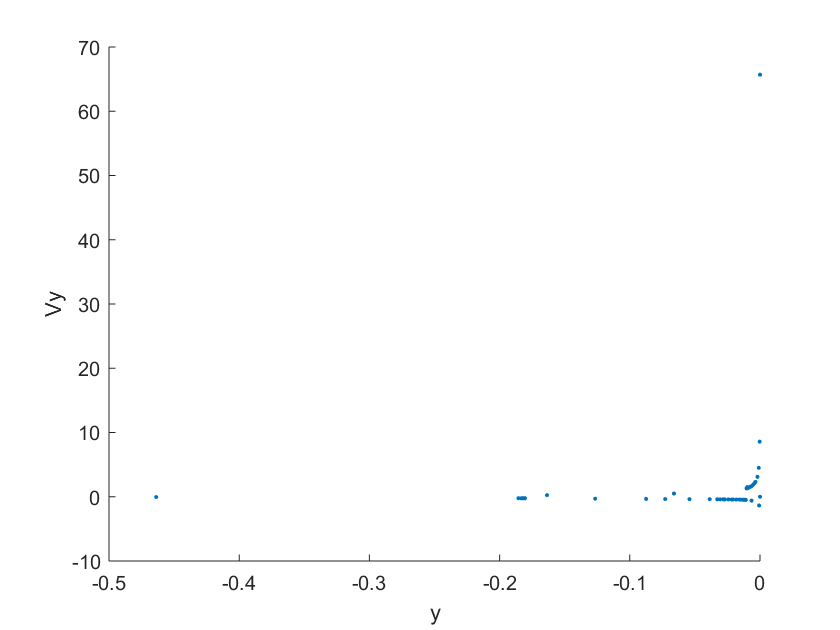

STM = reshape(eye(4),16,[])';
Xunstable = [X0 STM]';
epsilon=1e-6;

[U2,U3] =poincareMap(Xunstable,mu,k,periodo,periodo*4);